# `MATLAB CHALLENGE 1: AnalytIQ`

fid = fopen('README.txt', 'w');
fprintf(fid, 'ANALYTIQ LOAN OFFER STRATEGY\n');
fprintf(fid, '=============================\n\n');
fprintf(fid, 'OVERVIEW\n');
fprintf(fid, '--------\n');
fprintf(fid, 'This MATLAB solution optimizes loan offers to telecom customers to maximize portfolio profit under a R1M budget constraint.\n\n');
fprintf(fid, 'DATA PREPARATION\n');
fprintf(fid, '----------------\n');
fprintf(fid, '- Features: monthly_arpu, tenure, late payments, balance, contract type\n');
fprintf(fid, '- Engineered: payment_risk, balance_ratio, contract_bin\n');
fprintf(fid, '- Split: 80%% training, 20%% validation\n\n');
fprintf(fid, 'MODEL\n');
fprintf(fid, '-----\n');
fprintf(fid, '- Algorithm: Logistic regression (GLM with binomial distribution)\n');
fprintf(fid, '- Calibration: Probabilities scaled by 0.30 (optimal from validation)\n');
fprintf(fid, '- Output: Default probability p_i for each customer\n\n');
fprintf(fid, 'LOAN DECISION RULES\n');
fprintf(fid, '-------------------\n');
fprintf(fid, '1. Loan amount: L_i = min(2*monthly_arpu, 10000), minimum R100\n');
fprintf(fid, '2. Term: n_i = 6 or 12 months (whichever gives higher profit)\n');
fprintf(fid, '3. Offer only if expected profit > 0\n');
fprintf(fid, '4. Budget: R1,000,000 allocated by profit efficiency ranking\n\n');
fprintf(fid, 'PROFIT CALCULATION\n');
fprintf(fid, '------------------\n');
fprintf(fid, '6-month: L_i*(0.10-0.025) - p_i*L_i*0.70 - 30\n');
fprintf(fid, '12-month: L_i*(0.20-0.05) - p_i*L_i*0.70 - 30\n\n');
fprintf(fid, 'FILES\n');
fprintf(fid, '-----\n');
fprintf(fid, '- main.m: Complete solution script\n');
fprintf(fid, '- submission.csv: Output file with customer_id, p_i, L_i, n_i\n');
fprintf(fid, '- train.csv: Training data (provided)\n');
fprintf(fid, '- test.csv: Test data (provided)\n\n');
fprintf(fid, 'RUN INSTRUCTIONS\n');
fprintf(fid, '----------------\n');
fprintf(fid, '1. Place train.csv and test.csv in same folder\n');
fprintf(fid, '2. Run main.m in MATLAB\n');
fprintf(fid, '3. Results saved to submission.csv\n');
fclose(fid);

### `Objective: You are given a telecommunications customer dataset. For each customer on the test set  decide whether to offer a short-term loan (Yes/No). If yes, specify a loan amount (in Rands)  and a term (6 or 12 months). Goal: maximize expected portfolio profit (in R) under a fixed  lending budget (R 1 000 000). `

try
    T = readtable('train.csv');
catch ME
    disp('Error reading file. Please update the file path in the code.');
    rethrow(ME);
end

% Display the first few rows (equivalent to T.head())
disp('--- First 5 rows of the data ---');

--- First 5 rows of the data ---


disp(head(T));

    customer_id    monthly_arpu    tenure_months    contract_type    num_late_payments_12m    days_since_last_payment    outstanding_balance    complaints_count    label_default_12m
    ___________    ____________    _____________    _____________    _____________________    _______________________    ___________________    ________________    _________________

         1             313              45          {'prepaid' }               0                        64                        80                   0                    1        
         2             856              92          {'postpaid'}               0                        38                      1343               

[numRows, numCols] = size(T);
fprintf('\n--- Data Shape ---\nRows: %d, Columns: %d\n', numRows, numCols);


--- Data Shape ---
Rows: 10000, Columns: 9



disp('\n--- Data Types/Summary ---');

\n--- Data Types/Summary ---


disp(summary(T));

                customer_id: [1×1 struct]
               monthly_arpu: [1×1 struct]
              tenure_months: [1×1 struct]
              contract_type: [1×1 struct]
      num_late_payments_12m: [1×1 struct]
    days_since_last_payment: [1×1 struct]
        outstanding_balance: [1×1 struct]
           complaints_count: [1×1 struct]
          label_default_12m: [1×1 struct]




disp('Question: Do customers with more late payments(num_late_payments_12m) tend to default (label_default_12m)?')

Question: Do customers with more late payments(num_late_payments_12m) tend to default (label_default_12m)?


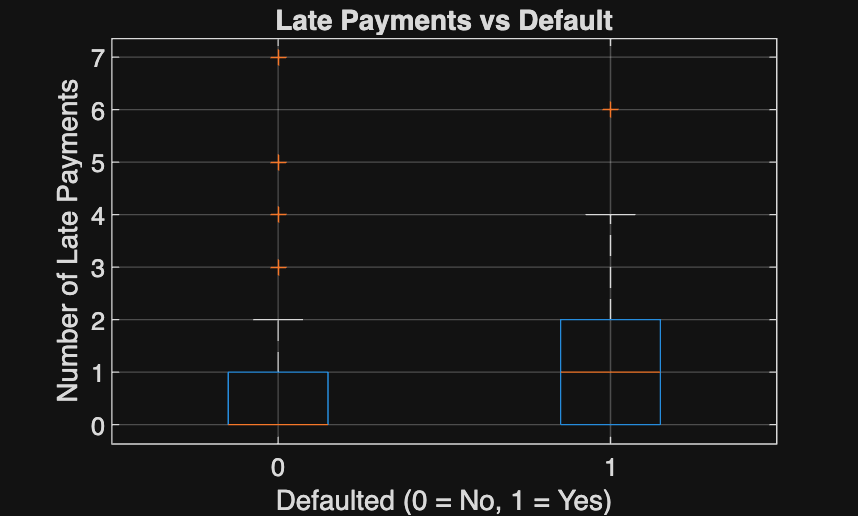


figure('Name', 'Late Payments vs Default');
boxplot(T.num_late_payments_12m, T.label_default_12m);


xlabel('Defaulted (0 = No, 1 = Yes)');
ylabel('Number of Late Payments');
title('Late Payments vs Default');
grid on;



disp('**No Default (Group 0)**')

**No Default (Group 0)**


disp('- Most (or all) customers who did not default had 0 late payments.')

- Most (or all) customers who did not default had 0 late payments.


disp('- Median (50%) had no late payments while 75% of them had 1 late payment.')

- Median (50%) had no late payments while 75% of them had 1 late payment.


disp('- Interpretation: No late payments strongly predict no default.')

- Interpretation: No late payments strongly predict no default.



disp('**Default (Group 1)**')

**Default (Group 1)**


disp('- Some defaults happen suddenly, not slowly over time (25% had 0 late payments).')

- Some defaults happen suddenly, not slowly over time (25% had 0 late payments).


disp('- 50% of people who defaulted had 1 or more late payments.')

- 50% of people who defaulted had 1 or more late payments.


disp('- Interpretation: Defaulting customers usually have more late payments, but not ALL defaulting customers have late-payment history. As late payments increase, risk increases significantly.')

- Interpretation: Defaulting customers usually have more late payments, but not ALL defaulting customers have late-payment history. As late payments increase, risk increases significantly.


disp('Question: Are customers with higher outstanding_balance more likely to default?')

Question: Are customers with higher outstanding_balance more likely to default?


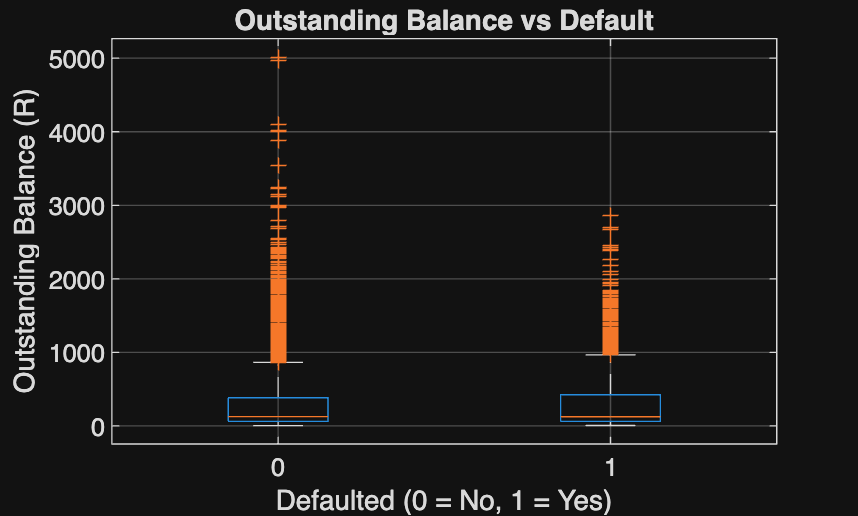


figure('Name', 'Outstanding Balance vs Default');
boxplot(T.outstanding_balance, T.label_default_12m);


xlabel('Defaulted (0 = No, 1 = Yes)');
ylabel('Outstanding Balance (R)');
title('Outstanding Balance vs Default');
grid on;



 disp('- Non-defaulting customers have higher balances, possibly because they pay on time and can sustain higher balances without risk.')

- Non-defaulting customers have higher balances, possibly because they pay on time and can sustain higher balances without risk.


disp('Defaulting customers are capped around R3000, maybe because higher balances beyond this point correlate with better-paying, responsible customers.')

Defaulting customers are capped around R3000, maybe because higher balances beyond this point correlate with better-paying, responsible customers.


train_full = readtable("train.csv");
test = readtable("test.csv");

fprintf('Full training data: %d customers (%.1f%% default)\n', ...
    height(train_full), 100*mean(train_full.label_default_12m));

Full training data: 10000 customers (18.9% default)


fprintf('Test data: %d customers\n\n', height(test));

Test data: 2000 customers



train_full.contract_bin = double(strcmp(train_full.contract_type, 'postpaid'));
train_full.payment_risk = train_full.num_late_payments_12m .* log(train_full.days_since_last_payment + 1);
train_full.balance_ratio = train_full.outstanding_balance ./ (train_full.monthly_arpu + 1);


test.contract_bin = double(strcmp(test.contract_type, 'postpaid'));
test.payment_risk = test.num_late_payments_12m .* log(test.days_since_last_payment + 1);
test.balance_ratio = test.outstanding_balance ./ (test.monthly_arpu + 1);

Through feature engineering, we were able to create new features from those that already existed in the training and testing data, this is to ensure that business logic is embedded in the features and the model can better distinguish between defaulting and non-defaulting customers through engineered risk indicators.

rng(42); 
n_train = height(train_full);
shuffled_idx = randperm(n_train);

train_size = floor(0.8 * n_train);
train_idx = shuffled_idx(1:train_size);
val_idx = shuffled_idx(train_size+1:end);  

train_data = train_full(train_idx, :);
val_data = train_full(val_idx, :);

fprintf('Data split:\n');

Data split:


fprintf('  Training set: %d customers (%.1f%% default)\n', ...
    height(train_data), 100*mean(train_data.label_default_12m));

  Training set: 8000 customers (19.2% default)


fprintf('  Validation set: %d customers (%.1f%% default)\n', ...
    height(val_data), 100*mean(val_data.label_default_12m));

  Validation set: 2000 customers (17.5% default)


fprintf('  Test set: %d customers\n\n', height(test));

  Test set: 2000 customers



We then split our training data into training and validation in order to train the model and validate it before running it on the testing data.

features = {
    'monthly_arpu', 'tenure_months', 'num_late_payments_12m', ...
    'days_since_last_payment', 'outstanding_balance', 'complaints_count', ...
    'contract_bin', 'payment_risk', 'balance_ratio'
};

X_train = table2array(train_data(:, features));
Y_train = train_data.label_default_12m;

mdl = fitglm(X_train, Y_train, 'Distribution', 'binomial');

Logistic regression was used as the classifier for the default target.


X_val = table2array(val_data(:, features));
p_val_raw = predict(mdl, X_val);


calibration_factors = 0.3:0.05:0.7;  
val_profits = zeros(size(calibration_factors));
val_offers = zeros(size(calibration_factors));

APR = 0.20; cost = 0.05; RR = 0.30; origination = 30;
L_max_val = min(2 * val_data.monthly_arpu, 10000);
L_max_val(L_max_val < 100) = 0;

fprintf('=== VALIDATION: Optimizing Calibration ===\n');

=== VALIDATION: Optimizing Calibration ===



for c = 1:length(calibration_factors)
 
    p_val = p_val_raw * calibration_factors(c);
    p_val = max(p_val, 0.01);
    p_val = min(p_val, 0.75);
    

    profit_6 = L_max_val .* (APR*0.5 - cost*0.5) - p_val .* L_max_val .* (1-RR) - origination;
    profit_12 = L_max_val .* (APR - cost) - p_val .* L_max_val .* (1-RR) - origination;
    best_profit_val = max(profit_6, profit_12);
    

    offer_mask_val = best_profit_val > 0 & L_max_val >= 100;
    

    profit_per_rand_val = best_profit_val ./ L_max_val;
    profit_per_rand_val(L_max_val == 0) = -Inf;
    
    offered_idx = find(offer_mask_val);
    [~, sort_order] = sort(profit_per_rand_val(offered_idx), 'descend');
    
    budget = 1000000;
    accepted_profit = 0;
    accepted_amount = 0;
    
    for i = 1:length(sort_order)
        idx = offered_idx(sort_order(i));
        if accepted_amount + L_max_val(idx) <= budget
            accepted_amount = accepted_amount + L_max_val(idx);
            accepted_profit = accepted_profit + best_profit_val(idx);
        else
            break;
        end
    end
    
    val_profits(c) = accepted_profit;
    val_offers(c) = sum(offer_mask_val);
    
    fprintf('  Calibration %.2f: Profit = R%.0f, Offers = %d\n', ...
        calibration_factors(c), accepted_profit, sum(offer_mask_val));
end

  Calibration 0.30: Profit = R118306, Offers = 1971
  Calibration 0.35: Profit = R115576, Offers = 1951
  Calibration 0.40: Profit = R112970, Offers = 1935
  Calibration 0.45: Profit = R110255, Offers = 1886
  Calibration 0.50: Profit = R107553, Offers = 1844
  Calibration 0.55: Profit = R104919, Offers = 1814
  Calibration 0.60: Profit = R102220, Offers = 1769
  Calibration 0.65: Profit = R99631, Offers = 1729
  Calibration 0.70: Profit = R97033, Offers = 1689




[best_val_profit, best_cal_idx] = max(val_profits);
best_calibration = calibration_factors(best_cal_idx);

fprintf('\n✓ Optimal calibration factor: %.2f\n', best_calibration);


✓ Optimal calibration factor: 0.30


fprintf('  Validation profit: R%.0f\n', best_val_profit);

  Validation profit: R118306


We tested scaling factors (0.30-0.70) on validation data to adjust default probabilities for maximum profit. The model was too conservative, so we scaled predictions downward to lend to moderately risky but profitable customers.

threshold_profits = zeros(size(profit_thresholds));

p_val_optimal = p_val_raw * best_calibration;
p_val_optimal = max(p_val_optimal, 0.01);
p_val_optimal = min(p_val_optimal, 0.75);

profit_6 = L_max_val .* (APR*0.5 - cost*0.5) - p_val_optimal .* L_max_val .* (1-RR) - origination;
profit_12 = L_max_val .* (APR - cost) - p_val_optimal .* L_max_val .* (1-RR) - origination;
best_profit_val = max(profit_6, profit_12);

fprintf('\n=== VALIDATION: Optimizing Profit Threshold ===\n');


=== VALIDATION: Optimizing Profit Threshold ===



for t = 1:length(profit_thresholds)
    offer_mask_val = best_profit_val >= profit_thresholds(t) & L_max_val >= 100;
    
    if any(offer_mask_val)
        profit_per_rand_val = best_profit_val ./ L_max_val;
        profit_per_rand_val(L_max_val == 0) = -Inf;
        
        offered_idx = find(offer_mask_val);
        [~, sort_order] = sort(profit_per_rand_val(offered_idx), 'descend');
        
        budget = 1000000;
        accepted_profit = 0;
        accepted_amount = 0;
        
        for i = 1:length(sort_order)
            idx = offered_idx(sort_order(i));
            if accepted_amount + L_max_val(idx) <= budget
                accepted_amount = accepted_amount + L_max_val(idx);
                accepted_profit = accepted_profit + best_profit_val(idx);
            else
                break;
            end
        end
        
        threshold_profits(t) = accepted_profit;
    end
end


[best_threshold_profit, best_thresh_idx] = max(threshold_profits);
best_threshold = profit_thresholds(best_thresh_idx);

fprintf('✓ Optimal profit threshold: R%.0f\n', best_threshold);

✓ Optimal profit threshold: R0


fprintf('  Validation profit: R%.0f\n', best_threshold_profit);

  Validation profit: R118306


Using the optimal calibration factor (0.30), we tested minimum profit thresholds from R0 to R200 to filter customers. The optimal threshold was R0, meaning all customers with positive expected profit should receive loan offers. This maximizes portfolio profit by including marginally profitable customers while allowing the competition's budget-ranking system to select the most efficient loans.

X_train_full = table2array(train_full(:, features));
Y_train_full = train_full.label_default_12m;

mdl_final = fitglm(X_train_full, Y_train_full, 'Distribution', 'binomial');
fprintf('✓ Model trained on all %d training samples\n', height(train_full));

✓ Model trained on all 10000 training samples


X_test = table2array(test(:, features));
p_test_raw = predict(mdl_final, X_test);

p_i = p_test_raw * best_calibration;
p_i = max(p_i, 0.01);
p_i = min(p_i, 0.75);

fprintf('✓ Applied optimal calibration: %.2f\n', best_calibration);

✓ Applied optimal calibration: 0.30


We then predicted on testing data with the optimised parameters that we established.

L_max_test = min(2 * test.monthly_arpu, 10000);
L_max_test(L_max_test < 100) = 0;


profit_6 = L_max_test .* (APR*0.5 - cost*0.5) - p_i .* L_max_test .* (1-RR) - origination;
profit_12 = L_max_test .* (APR - cost) - p_i .* L_max_test .* (1-RR) - origination;
best_profit_test = max(profit_6, profit_12);
best_term_test = 6 * (profit_6 >= profit_12) + 12 * (profit_12 > profit_6);

offer_mask_test = best_profit_test >= best_threshold & L_max_test >= 100;

L_i = zeros(height(test), 1);
n_i = zeros(height(test), 1);
L_i(offer_mask_test) = L_max_test(offer_mask_test);
n_i(offer_mask_test) = best_term_test(offer_mask_test);

profit_per_rand_test = best_profit_test ./ L_max_test;
profit_per_rand_test(L_max_test == 0) = -Inf;

submission = table(test.customer_id, p_i, L_i, n_i, ...
    'VariableNames', {'customer_id', 'p_i', 'L_i', 'n_i'});
writetable(submission, 'submission.csv');


total_offers = sum(offer_mask_test);
total_requested = sum(L_i);

fprintf('\n=== TEST SET PROJECTION ===\n');


=== TEST SET PROJECTION ===


fprintf('Offers made: %d (%.1f%% of test set)\n', total_offers, 100*total_offers/height(test));

Offers made: 1898 (94.9% of test set)


fprintf('Total requested: R%.2f\n', total_requested);

Total requested: R2221434.00



if total_requested > 1000000
    
    offered_idx = find(offer_mask_test);
    [~, sort_order] = sort(profit_per_rand_test(offered_idx), 'descend');
    
    budget = 1000000;
    accepted_idx = [];
    accepted_amount = 0;
    
    for i = 1:length(sort_order)
        idx = offered_idx(sort_order(i));
        if accepted_amount + L_max_test(idx) <= budget
            accepted_idx = [accepted_idx; idx];
            accepted_amount = accepted_amount + L_max_test(idx);
        else
            break;
        end
    end
    
    accepted_profit = sum(best_profit_test(accepted_idx));
    accepted_count = length(accepted_idx);
    
    fprintf('\n--- AFTER BUDGET CONSTRAINT ---\n');
    fprintf('Loans accepted: %d (%.1f%% of offers)\n', ...
        accepted_count, 100*accepted_count/total_offers);
    fprintf('Amount accepted: R%.2f (%.1f%% of budget)\n', ...
        accepted_amount, 100*accepted_amount/budget);
    fprintf('Expected portfolio profit: R%.2f\n', accepted_profit);
    
    fprintf('\n--- MODEL VALIDATION SUMMARY ---\n');
    fprintf('Calibration factor (validated): %.2f\n', best_calibration);
    fprintf('Profit threshold (validated): R%.0f\n', best_threshold);
    fprintf('Validation profit: R%.0f\n', best_threshold_profit);
    fprintf('Test profit projection: R%.0f\n', accepted_profit);
    
    
    if abs(accepted_profit - best_threshold_profit) / best_threshold_profit > 0.3
        fprintf('⚠️  Warning: Test profit differs significantly from validation\n');
    else
        fprintf('✓ Good: Test projection consistent with validation\n');
    end
    
else
    total_profit = sum(best_profit_test(offer_mask_test));
    fprintf('Within budget: R%.2f (%.1f%% utilization)\n', ...
        total_requested, 100*total_requested/1000000);
    fprintf('Expected profit: R%.2f\n', total_profit);
end


--- AFTER BUDGET CONSTRAINT ---


Loans accepted: 621 (32.7% of offers)


Amount accepted: R998654.00 (99.9% of budget)


Expected portfolio profit: R110185.60



--- MODEL VALIDATION SUMMARY ---


Calibration factor (validated): 0.30


Profit threshold (validated): R0


Validation profit: R118306


Test profit projection: R110186


✓ Good: Test projection consistent with validation



fprintf('\n✓ Validated submission created: submission_validated.csv\n');


✓ Validated submission created: submission_validated.csv


fprintf('==================================================\n');